ssid = "TEST_BEACON";
beaconInterval = 100;
band = 2.4;
chNum = 6;

frameBodyConfig = wlanMACManagementConfig( ...
    BeaconInterval=beaconInterval, ...
    SSID=ssid);

dsElementID = 3;
dsInformation = dec2hex(chNum,2);
frameBodyConfig = frameBodyConfig.addIE(dsElementID,dsInformation);

beaconFrameConfig = wlanMACFrameConfig(FrameType="Beacon", ...
    ManagementConfig=frameBodyConfig);

[mpduBits,mpduLength] = wlanMACFrame(beaconFrameConfig,OutputFormat="bits");

fc = wlanChannelFrequency(chNum,band);

cfgNonHT = wlanNonHTConfig(PSDULength=61);

osf = 1;
tbtt = beaconInterval*1024e-6;
txWaveform = wlanWaveformGenerator(mpduBits,cfgNonHT,... 
    OversamplingFactor=osf,Idletime=tbtt);

Rs = wlanSampleRate(cfgNonHT,OversamplingFactor=osf);

txWaveform = [zeros(10, 1); txWaveform];

txWaveform = awgn(txWaveform * (-0.1 + 0.5i), 60);

## Packet Detection

rfRxFreq = 2.437e9;

% rx = comm.SDRuReceiver( ...
%     'Platform',         'B210', ...
%     'SerialNum',        '344C4DE', ...
%     'MasterClockRate', 20e6, ...
%     'CenterFrequency',  rfRxFreq,...
%     'Gain', 30,...
%     'OutputDataType', 'double');

rxData = txWaveform;

detect the packet

startOffset = wlanPacketDetect(rxData,'CBW20')

startOffset = 4

Calculate the LLTF index points

idxLLTF = wlanFieldIndices(cfgNonHT, 'L-LTF')

idxLLTF = 1×2 uint32 row vector
   161   320


Get non-HT fields

ind = wlanFieldIndices(cfgNonHT);
nonHTFields = rxData(startOffset+(ind.LSTF(1):ind.LSIG(2)),:);

Demodulate the LLTF 

demodSig = wlanLLTFDemodulate(nonHTFields(idxLLTF(1):idxLLTF(2), :), cfgNonHT);

Get channel estimation

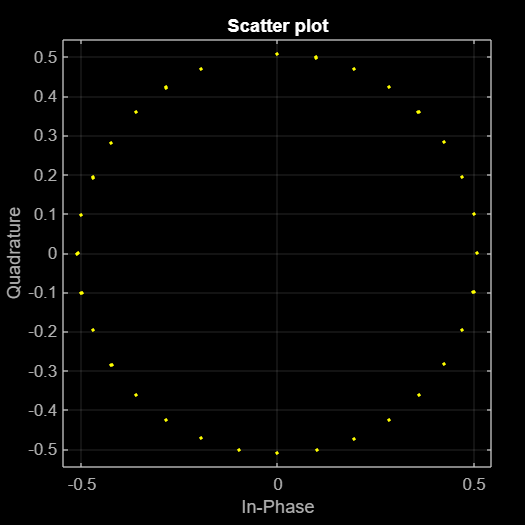

est = wlanLLTFChannelEstimate(demodSig, cfgNonHT);
scatterplot(est);
grid;